# 2223-MA378 : Lab 2 [SOLUTION]

Lab 2 of Numerical Analysis 2: Experiments with spline interpolation (solution).

## Exercise 0

Change the data at the start of this file to include your name, ID number and email address.

- Name: Student O'Student 

- ID: 01234567

- Email:  `s.ostudent321@universityofgalway.ie`

## Verifying Convergence

We'll verify that the method converges at a rate that is proportional to $h^2 = N^{-2}$. For that, we'll use a for loop:

k=0;
Ns = [4, 8, 16, 32, 64, 128, 256, 512, 2014]; % the values of $N$ we'll use
for N=Ns
   k=k+1;
   h = 1/N;
   x = 0:h:1;
   l = interp1(x, f(x), 'linear', 'pp');
   xp = 0:h/10:1;
   Errors(k)=max(abs(f(xp)-ppval(l, xp)));
   fprintf('N=%4d, h=%8.2e, ||f-l||=%9.3e\n', Ns(k) , h, Errors(k));
end
subplot(1,1,1);loglog(Ns, Errors, ':o', Ns, Ns.^(-2), '--');
legend('Errors', 'N^{-2}')

You should observe that, in this log-log plot, the lines representing the errors and $N^{-2}$ are parallel. This implies that, indeed, the error is proportional to $h^2$. 

### **EXERCISE 1** : Find C

We expect that the error is (approximately) $Ch^2$. Use the data above to estimate $C$. Use that value of $C$ to determine the value of $N$ you'd need to take to ensure that the error is no more than $10^{-12}$. Show your calcuations in MATLAB. 

**YOUR CODE GOES HERE:**

% We can estimate C by trail and error. You should find it is about 3
% To be more precise, we can use that C \approx Errors*N^2

N=   4, h=2.50e-01, ||f-l||=1.812e-01
N=   8, h=1.25e-01, ||f-l||=4.990e-02
N=  16, h=6.25e-02, ||f-l||=1.264e-02
N=  32, h=3.12e-02, ||f-l||=3.178e-03
N=  64, h=1.56e-02, ||f-l||=7.949e-04
N= 128, h=7.81e-03, ||f-l||=1.988e-04
N= 256, h=3.91e-03, ||f-l||=4.971e-05
N= 512, h=1.95e-03, ||f-l||=1.243e-05
N=2014, h=4.97e-04, ||f-l||=8.032e-07


C = mean(Errors.*(Ns.^2))
C=3
subplot(1,1,1);loglog(Ns, Errors, ':o', Ns, C*Ns.^(-2), '--');
legend('Errors', 'C*N^{-2}')

## Cubic Spline Interpolant

### EXERCISE 2: Verify convergence

Taking $f=\sin(\pi x)$ and $x_0=0$, $x_N=1$, verify that $\| f - S \|_\infty \leq C h^4$, and estimate the value of $C$. Do this by producing a log-log plot of $\|f-S\|_\infty$ against $N$.

#### SOLUTION:

k=0;

C = 3.2077

Ns = [4, 8, 16, 32, 64, 128, 256, 512, 2014]; % the values of $N$ we'll use

C = 3

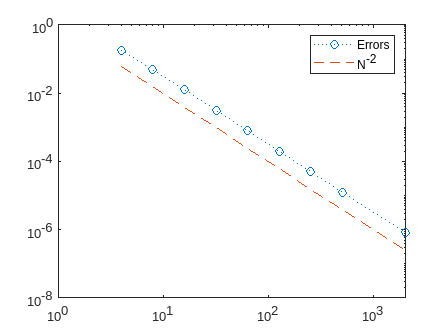

for N=Ns

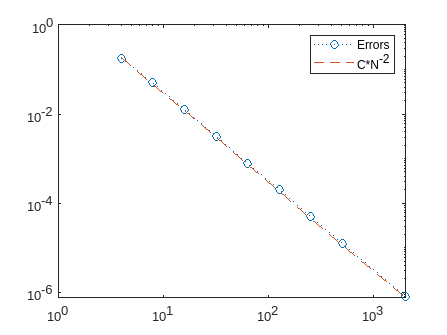

   k=k+1;

   h = 1/N;
   x = 0:h:1;
   l = interp1(x, f(x), 'spline', 'pp');
   xp = 0:h/10:1;
   Errors(k)=max(abs(f(xp)-ppval(l, xp)));
   fprintf('N=%4d, h=%8.2e, ||f-l||=%9.3e\n', Ns(k) , h, Errors(k));
end
subplot(1,1,1);loglog(Ns, Errors, ':o', Ns, Ns.^(-4), '--');
legend('Errors', 'N^{-4}')


N=   4, h=2.50e-01, ||f-l||=5.509e-02
N=   8, h=1.25e-01, ||f-l||=9.104e-03
N=  16, h=6.25e-02, ||f-l||=6.883e-04
N=  32, h=3.12e-02, ||f-l||=4.315e-05
N=  64, h=1.56e-02, ||f-l||=2.623e-06
N= 128, h=7.81e-03, ||f-l||=1.603e-07
N= 256, h=3.91e-03, ||f-l||=9.881e-09
N= 512, h=1.95e-03, ||f-l||=6.129e-10
N=2014, h=4.97e-04, ||f-l||=2.545e-12


## How accurate is PCHIP interpolation?

### EXERCISE 3: Determine the order of accuracy of MATLAB's `pchip` method.

Using a approach similar to how we verified the order of convergence of the '`linear`' and '`spline`' methods, determine the order of accuracy of the '`pchip`' method.

#### SOLUTION

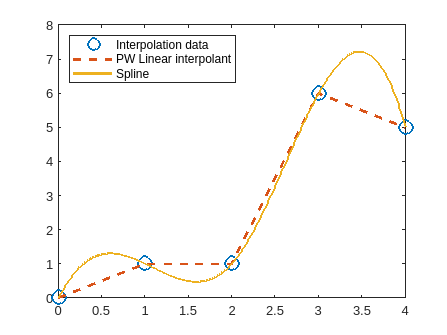

k=0;

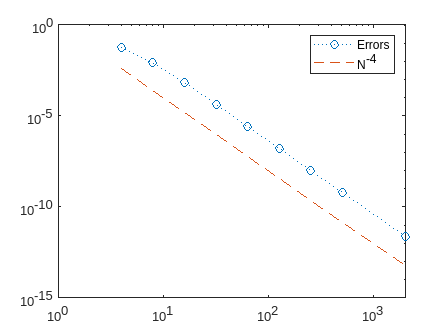

Ns = [4, 8, 16, 32, 64, 128, 256, 512, 2014]; % the values of $N$ we'll use

N=   4, h=2.50e-01, ||f-l||=5.301e-02
N=   8, h=1.25e-01, ||f-l||=2.674e-02
N=  16, h=6.25e-02, ||f-l||=6.711e-03
N=  32, h=3.12e-02, ||f-l||=1.847e-03
N=  64, h=1.56e-02, ||f-l||=3.596e-04
N= 128, h=7.81e-03, ||f-l||=1.481e-04
N= 256, h=3.91e-03, ||f-l||=1.178e-05
N= 512, h=1.95e-03, ||f-l||=3.114e-06
N=2014, h=4.97e-04, ||f-l||=2.506e-07


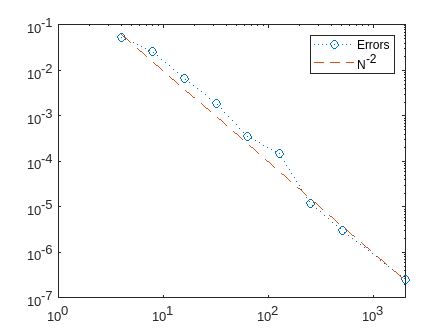

for N=Ns
   k=k+1;
   h = 1/N;
   x = 0:h:1;
   l = interp1(x, f(x), 'pchip', 'pp');
   xp = 0:h/10:1;
   Errors(k)=max(abs(f(xp)-ppval(l, xp)));
   fprintf('N=%4d, h=%8.2e, ||f-l||=%9.3e\n', Ns(k) , h, Errors(k));
end
subplot(1,1,1);loglog(Ns, Errors, ':o', Ns, Ns.^(-2), '--');
legend('Errors', 'N^{-2}')

You should find that the error is proportional to $h^2$.